# **ASSIGNMENT 4**

clc
clear

**Import and prepare data**

fileID = fopen('omni2_24466.lst');
data = textscan(fileID,'%f');

data = reshape(data{1,1}.',[8,8760]);
data = data.';
[m, n] = size(data);

BY = data(:,4);
BZ = data(:,5);
WindSpeed = data(:,6);
Kp = data(:,7) ./ 10;
AL = data(:,8);

**Expansion coefficients for auroral boundaries**

b00 = [-0.07, -10.06, -4.44, -3.77, -6.61, 6.37, -4.48];
b10 = [24.54, 19.83, 7.47, 7.90, 10.17, -1.10, 10.16];
b20 = [-12.53, -9.33, -3.01, -4.73, -5.80, 0.34, -5.87];
b30 = [2.15, 1.24, 0.25, 0.91, 1.19, -0.38, 0.98];

b01 = [1.61, -9.59, -12.07, -6.56, -2.22, -23.98, -20.07];
b11 = [23.21, 17.78, 17.49, 11.44, 1.50, 42.79, 36.67];
b21 = [-10.97, -7.20, -7.96, -6.73, -0.58, -26.96, -24.20];
b31 = [2.03, 0.96, 1.15, 1.31, 0.08, 5.56, 5.11];

b02 = [3.44, -2.41, -0.74, -2.12, -1.68, 8.69, 8.61];
b12 = [29.77, 7.89, 3.94, 3.24, -2.48, -2.73, -5.34];
b22 = [-16.38, -4.32, -3.09, -1.67, 1.58, 13.03, -1.36];
b32 = [3.35, 0.87, 0.72, 0.31, -0.28, -2.14, 0.76];

AL_range = [-10, -100, -200, -300, -400, -500, -600, -700, -800];
al_size = size(AL_range);
al_number = al_size(2);

A_alpha_pole = zeros(al_number,7);
A_alpha_equator = zeros(al_number,7);
A_alpha_diffuse = zeros(al_number,7);

for i=1:al_number
    for j=1:7
        A_alpha_pole(i,j) = b00(j) + b10(j)*log10(abs(AL_range(i))) + b20(j)*log10(abs(AL_range(i)))^2 + b30(j)*log10(abs(AL_range(i)))^3;
        A_alpha_equator(i,j) = b01(j) + b11(j)*log10(abs(AL_range(i))) + b21(j)*log10(abs(AL_range(i)))^2 + b31(j)*log10(abs(AL_range(i)))^3;
        A_alpha_diffuse(i,j) = b02(j) + b12(j)*log10(abs(AL_range(i))) + b22(j)*log10(abs(AL_range(i)))^2 + b32(j)*log10(abs(AL_range(i)))^3;
    end
end

theta_pole = zeros(al_number,24);
theta_equator = zeros(al_number,24);
theta_diffuse = zeros(al_number,24);

for i=1:al_number
    for t=0:23
        theta_pole(i,t+1) = 90 - A_alpha_pole(i,1) + A_alpha_pole(i,2)*cos(15*(t+A_alpha_pole(i,5))*pi/180) + A_alpha_pole(i,3)*cos(15*(2*t+A_alpha_pole(i,6))*pi/180) + A_alpha_pole(i,4)*cos(15*(3*t+A_alpha_pole(i,7))*pi/180);
        theta_equator(i,t+1) = 90 - A_alpha_equator(i,1) + A_alpha_equator(i,2)*cos(15*(t+A_alpha_equator(i,5))*pi/180) + A_alpha_equator(i,3)*cos(15*(2*t+A_alpha_equator(i,6))*pi/180) + A_alpha_equator(i,4)*cos(15*(3*t+A_alpha_equator(i,7))*pi/180);
        theta_diffuse(i,t+1) = 90 - A_alpha_diffuse(i,1) + A_alpha_diffuse(i,2)*cos(15*(t+A_alpha_diffuse(i,5))*pi/180) + A_alpha_diffuse(i,3)*cos(15*(2*t+A_alpha_diffuse(i,6))*pi/180) + A_alpha_diffuse(i,4)*cos(15*(3*t+A_alpha_diffuse(i,7))*pi/180);
    end
end

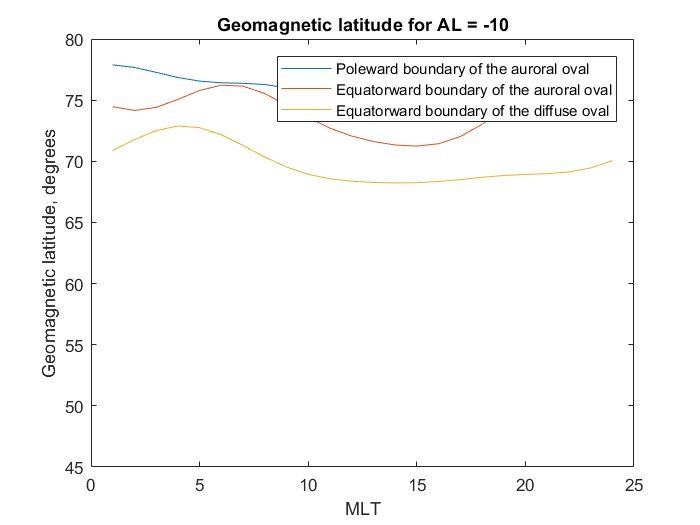

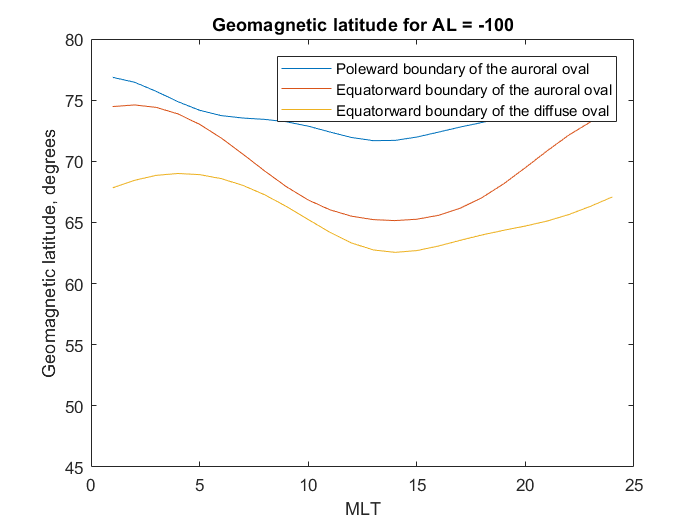

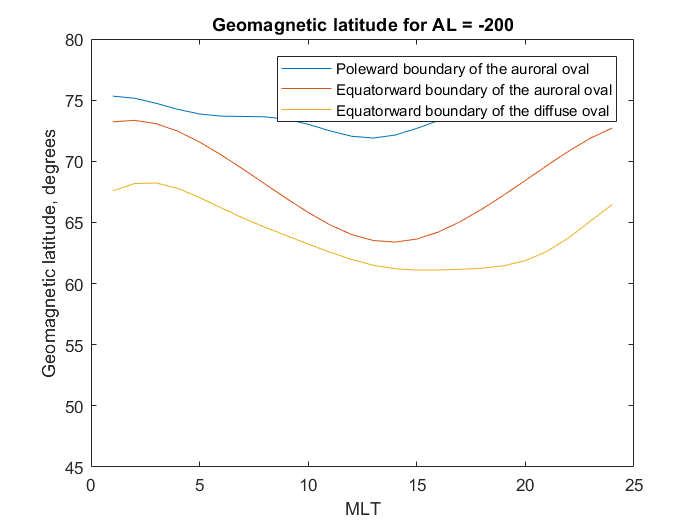

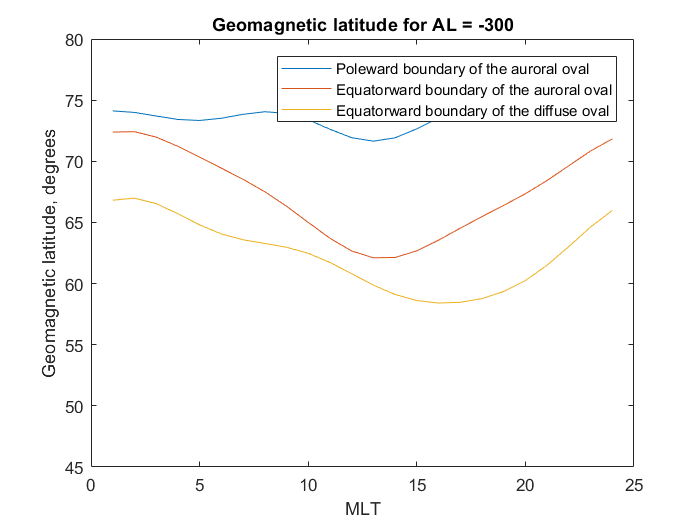

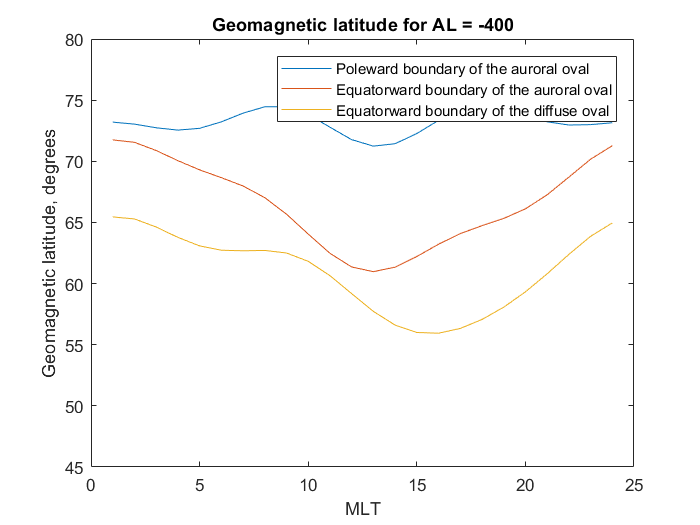

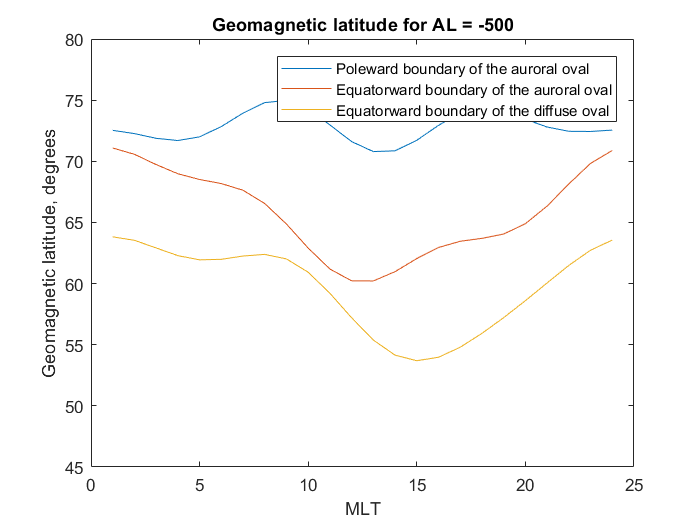

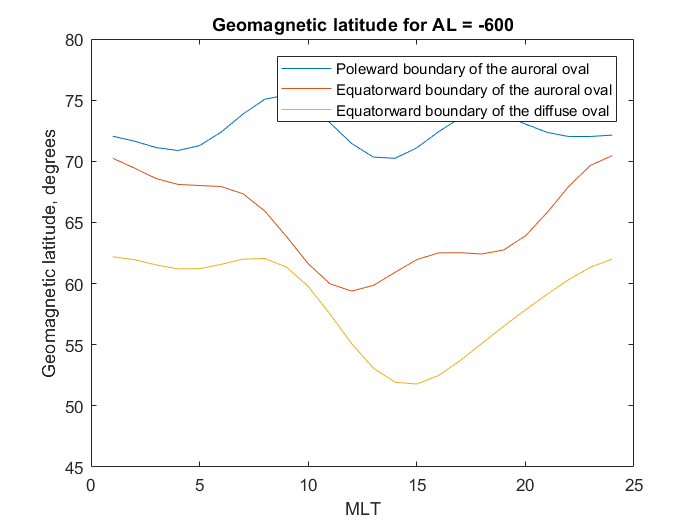

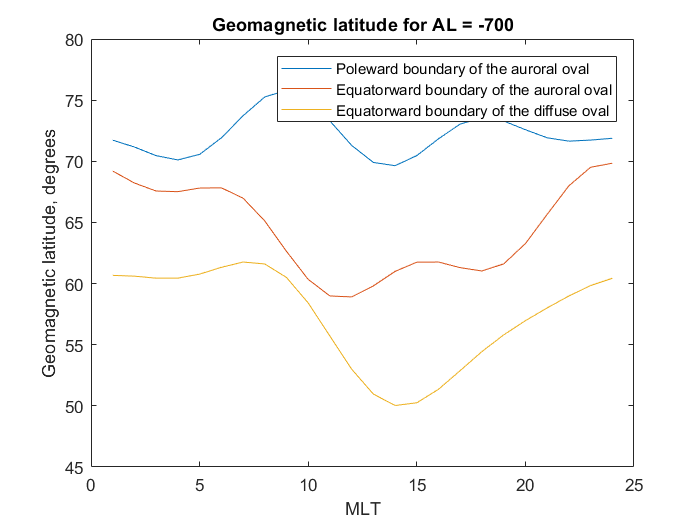

for i=1:al_number
    figure;
    
    plot(theta_pole(i,:));
    hold on;
    plot(theta_equator(i,:));
    hold on;
    plot(theta_diffuse(i,:));
    ylim([45 80]);
    
    title(['Geomagnetic latitude for AL = ' num2str(AL_range(i))]);
    xlabel('MLT'); 
    ylabel('Geomagnetic latitude, degrees') 
    legend('Poleward boundary of the auroral oval','Equatorward boundary of the auroral oval','Equatorward boundary of the diffuse oval');
end

**Reconstruction of AL index**

**a) Kp index approach**

c = [18, -12.3, 27.2, -2.0];

AL_KP_predicted = zeros(m,1);

for i=1:m
    AL_KP_predicted(i) = c(1) + c(2)*Kp(i) + c(3)*Kp(i)^2 + c(4)*Kp(i)^3;
end

AL_KP_predicted = -AL_KP_predicted;

RMSE = sqrt(immse(AL, AL_KP_predicted))

RMSE = 110.0472

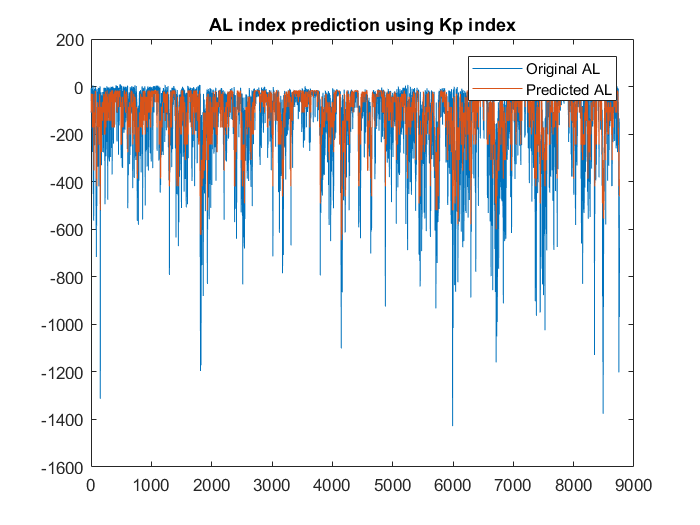

figure;
plot(AL);
hold on;
plot(AL_KP_predicted);

title("AL index prediction using Kp index");
legend("Original AL", "Predicted AL");

**b) Solar wind data approach**

AL_wind_predicted = zeros(m,1);
IMF_clock = zeros(m,1); 

IMF_clock(1) = acos(BZ(1) / sqrt(BY(i)^2 + BZ(i)^2));

for i=2:m
    if (BY(i) == BZ(i))
        IMF_clock(i) = IMF_clock(i-1);
    else
        IMF_clock(i) = acos(BZ(i) / sqrt(BY(i)^2 + BZ(i)^2));
    end
end

E = zeros(m,1); 
alpha = 0.0044;

for i=1:m
    E(i) = WindSpeed(i) * sqrt(BY(i)^2 / 2 + BZ(i)^2) * sin(IMF_clock(i)/2)^4 + alpha * WindSpeed(i)^2 * sin(IMF_clock(i)/2)^(0.5);
end

E185 = zeros(m,1);

for i=3:m
    E185(i) = (E(i-2) + 8*E(i-1) + 5*E(i)) / 14;
end

coef = polyfit(log10(E185(3:m)),AL(3:m),4);
y = polyval(coef,log10(E185(3:m)));

RMSE = sqrt(immse(AL(3:m), y))

RMSE = 89.9906

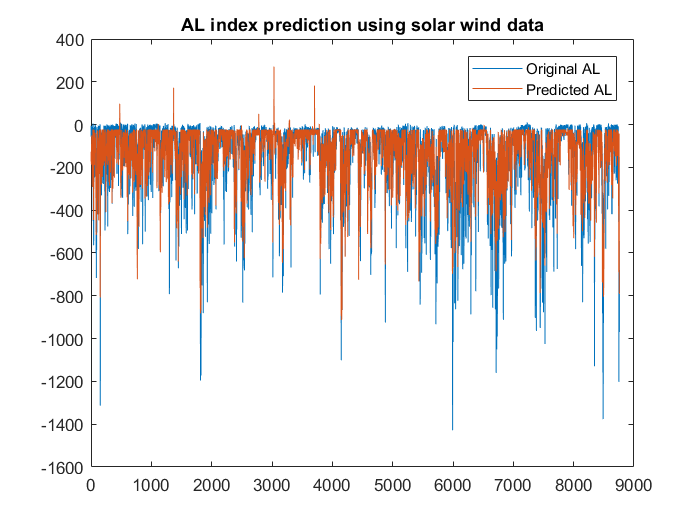

figure;
plot(AL);
hold on;
plot(y);

title("AL index prediction using solar wind data");
legend("Original AL", "Predicted AL");